Variables

clear
clc
K = 0.5305;
I = 0.0019;
L = 3.4*10^-3;
b = 0.000931;
R = 6.9;

For Position

s = tf('s');
P = (K)/(s*((I*s+b)*(L*s+R)+K))

P =
 
                 0.5305
  -------------------------------------
  6.46e-06 s^3 + 0.01311 s^2 + 0.5369 s
 
Continuous-time transfer function.



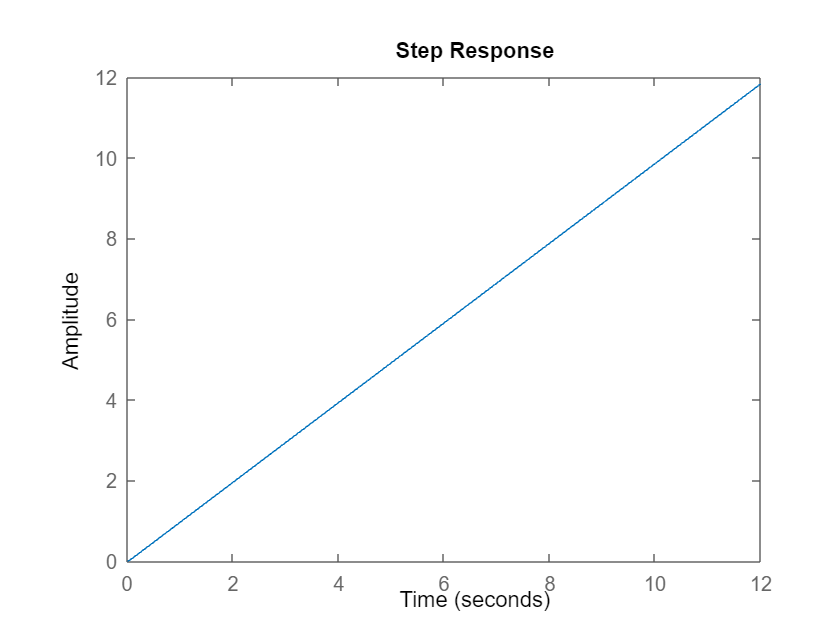

step(P)

For velocity

P_v = K / ((I*s+b)*(L*s+R)+K)

P_v =
 
               0.5305
  ---------------------------------
  6.46e-06 s^2 + 0.01311 s + 0.5369
 
Continuous-time transfer function.



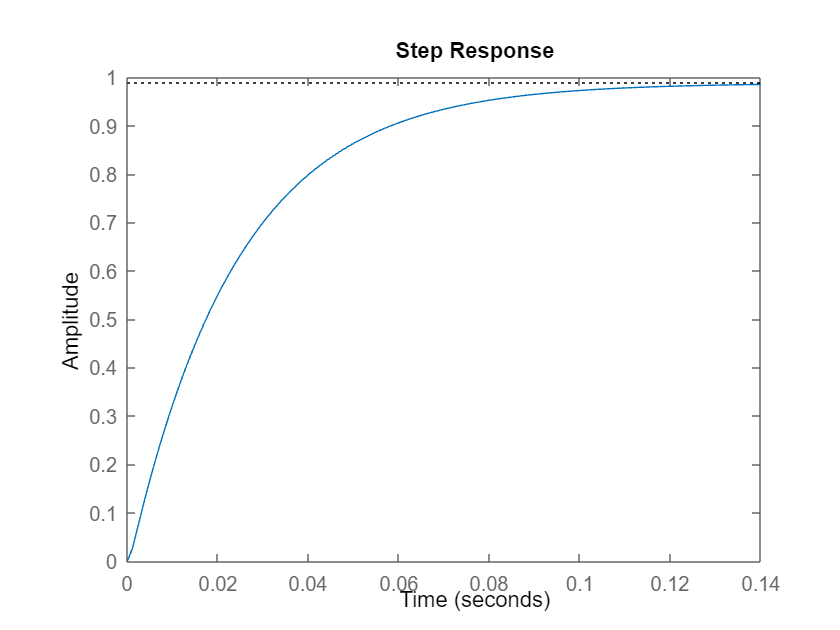

step(P_v)

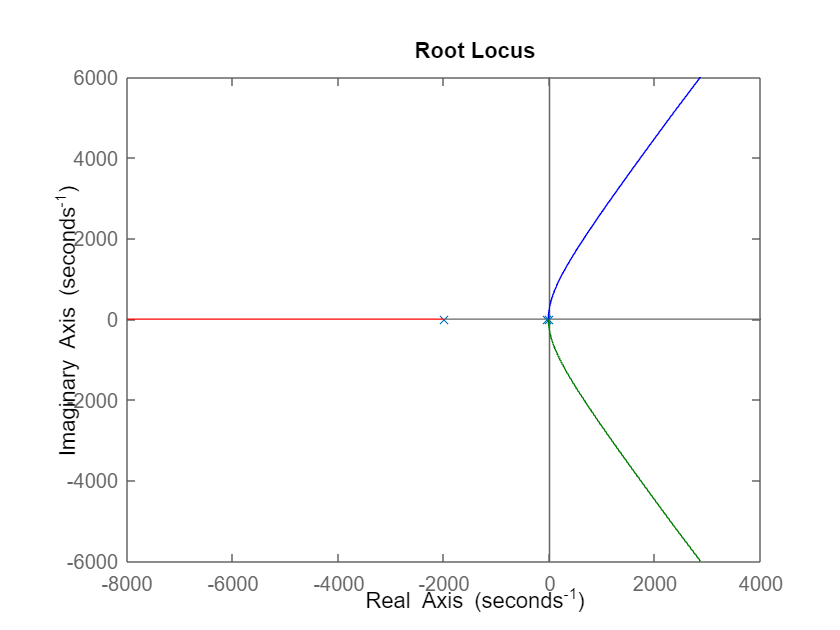

rlocus(P)

Designing PID regulator

Kp = 1;
Ki = 1;
Kd = 3;

C = pid(Kp,Ki,Kd);
sys = feedback(C*P,1)

sys =
 
                1.591 s^2 + 0.5305 s + 0.5305
  ----------------------------------------------------------
  6.46e-06 s^4 + 0.01311 s^3 + 2.128 s^2 + 0.5305 s + 0.5305
 
Continuous-time transfer function.



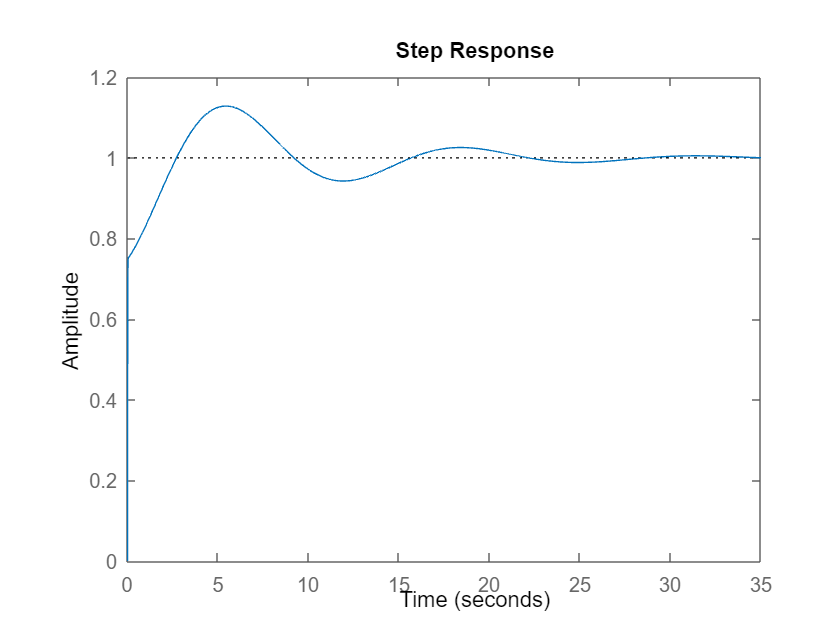

step(sys)

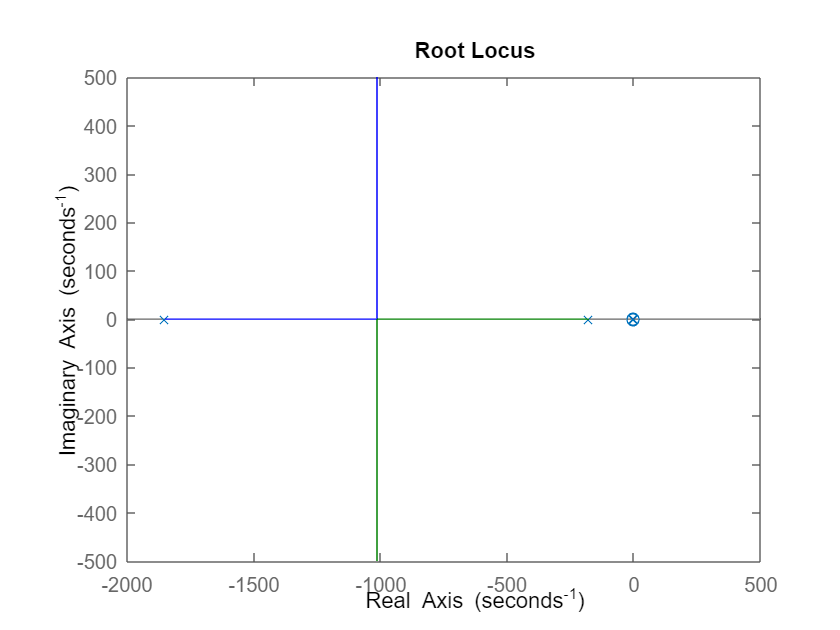

rlocus(sys)